# DC motor position: State Space

## State-space equation

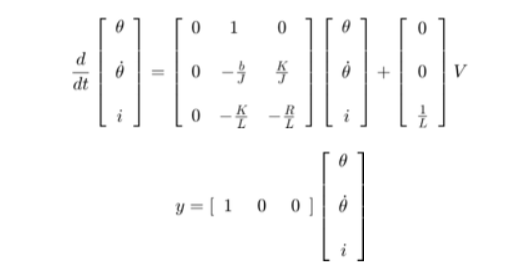

If the given system is controllable, then by designing a full state-feedback controller we can move these three poles anywhere we'd like

## Controlability

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;

A = [0 1 0
    0 -b/J K/J
    0 -K/L -R/L];
B = [0 ; 0 ; 1/L];
C = [1  0  0];
D = 0;
motor_ss = ss(A,B,C,D);
determinant = det(ctrb(A,B))

determinant = -3.4636e+24

Note: one can use rank command to check the full rank as well but rank command is not numerically reliable

## Full-state feedback

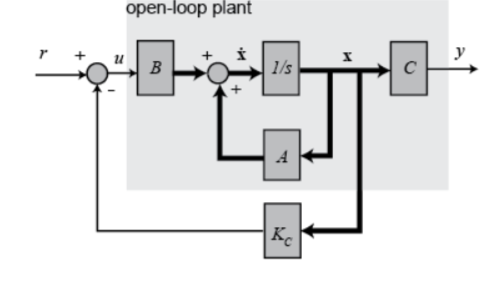

The system is third order, and we see all the states can be easily measured. Based on the requirements, we need all poles should be less than -100 and the damping ratio is larger than 0.5. So we pick the following 3 closed roots

p1 = -200;
p2 = -100-100i;
p3 = -100+100i;
Kc = place(A, B, [p1 p2 p3]);
sys_cl = ss(A-B*Kc, B, C, D);

the state-space equations become the following.

Then we can use a recaling factor in front of input r to make system has the preformance as we like too. But the requirments also say that there should be no error for the disturbance, lets see what is the output from the disturbance.

## Disturbance output

In order to observe the system's disturbance response, we must provide the proper input to the system. In this case, a disturbance is physically a load torque that acts on the inertia of the motor. This load torque acts as an additive term in the second state equation (which gets divided by J, as do all the other terms in this equation). We can simulate this simply by modifying our closed-loop input matrix, B , to have a  J in the second row assuming that our current input is only the disturbance

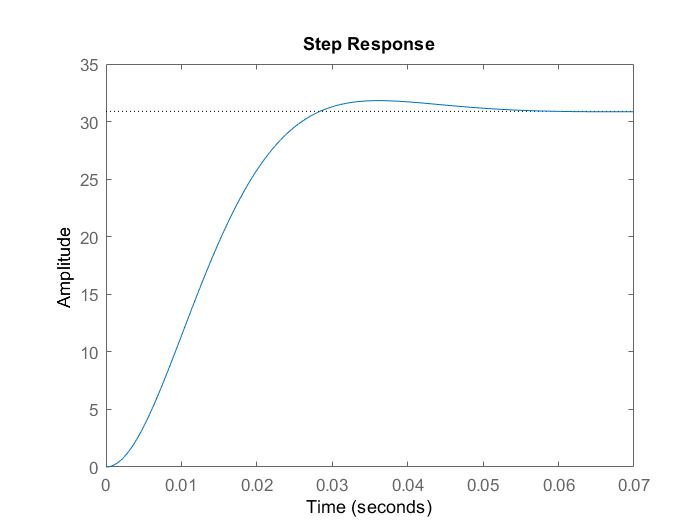

dist_cl = ss(A-B*Kc,[0; 1/J ; 0], C, D);
step(dist_cl);

**Since we can not add a rescaling term for the disturbance, we have nothing to do with the error caused by disturbance and this is not fitting our design requirements. Even though we can rescale the input to make the steady state error to be zero for the input, we could not make the steady state error from the disturbance as zero too. As a result, we need to add a controller.**

## Integreal Controller

From prior examples, we know that if we put an extra integrator in series with the plant it can remove the steady-state error due to a step reference. If the integrator comes before the injection of the disturbance, it will also cancel a step disturbance input in steady state. This changes our control structure so that it now resembles the block diagram shown in the following figure.

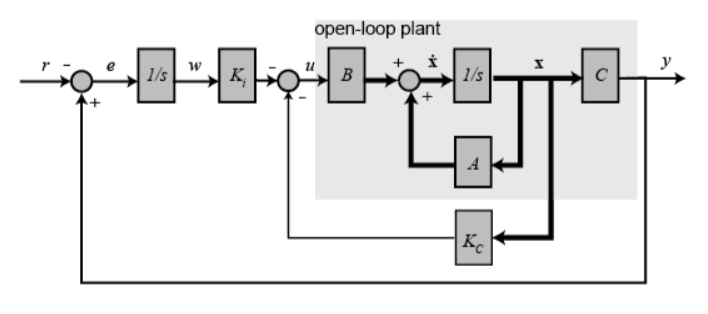

We can model the addition of this integrator by augmenting our state equations with an extra state w for the integral of the error which we will identify with the variable e = r - y. This adds an extra state equation, where the derivative of this state is then just the error,  

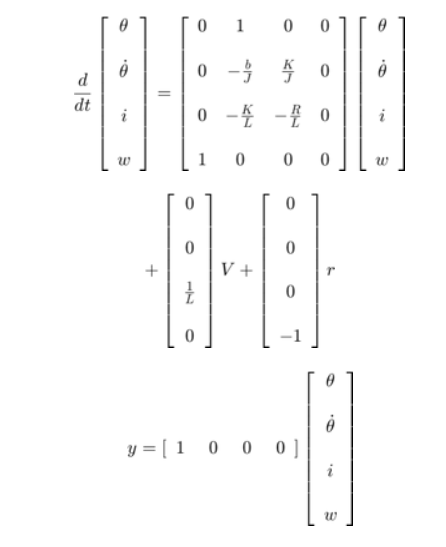

where for A matrix, the last row should be -1, for r matrix the last row should be +1. And V, should be u. Then u=-KcX + Kiw = -K_new*X_new. This helps to close the loop. And we use the same command to find the roots and corresponding K.

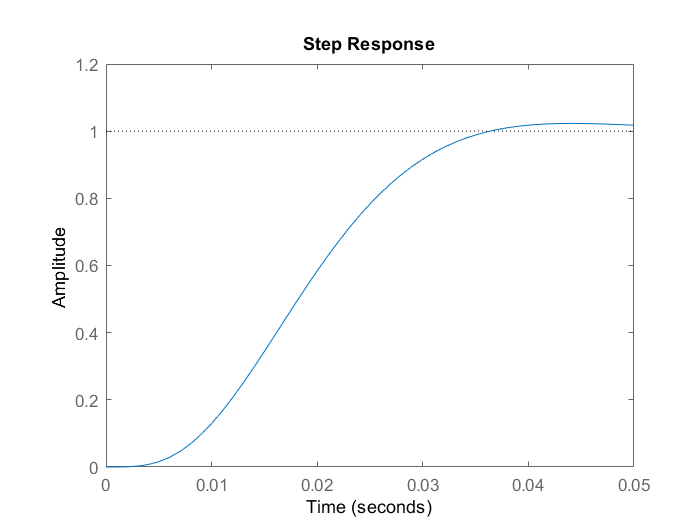

Aa = [0 1 0 0;
      0 -b/J K/J 0;
      0 -K/L -R/L 0;
      -1 0 0 0];
Ba = [0 ; 0 ; 1/L ; 0 ];
Br = [0 ; 0 ; 0; 1];
Ca = [1 0 0 0];
Da = [0];

p4 = -300;
Ka = place(Aa,Ba,[p1,p2,p3,p4]);

t = 0:0.001:.05;
sys_cl = ss(Aa-Ba*Ka,Br,Ca,Da);
step(sys_cl,t)